# **This MATLAB Live Script compares analytic and numerical**

# **solutions of CRPS of **$P=GEV\left(\mu ,\sigma \mathrm{²},\xi \right)$** of Vrugt, WRR (2024)**

**Quantile form of the CRPS [in negative orientation!]**


$$\mathrm{CRPS}\left(P,\omega \right)=\omega \left(2F\left(\omega \right)-1\right)-2\int_0^1 \tau F^{-1} \left(\tau \right)\mathrm{d}\tau +2\int_{F\left(\omega \right)}^1 F^{-1} \left(\tau \right)\mathrm{d}\tau$$


**Quantile function **$F^{-1} \left(\tau \right)$ **(= inverse CDF)** **of Generalized Extreme Value (GEV) distribution **$GEV\left(\mu ,\sigma^2 ,\xi \right)$** with location parameter **$\mu$, **scale parameter** $\sigma \mathrm{²}$ **and shape parameter** $\xi$ 

**GEV: Quantile function**

$F^{-1} \left(\tau \right)=\mu -\sigma \log \left(-\log \left(\tau \right)\right)$                               if $\xi =0$

$F^{-1} \left(\tau \right)=\mu +\frac{\sigma }{\xi }\left({\left(-\log \left(\tau \right)\right)}^{-\xi } -1\right)$                       if $\xi \not= 0$

**Lets first get an analytic expression for the first integral**

- 2 \int_{0}^{1} tau * F^{-1}(tau)d tau

**Integration by parts **

\int udv = u*v - \int v du

if u = tau, then du = 1

if dv = F^{-1}(tau), then v = int(mu + s/xi * ( (-log(tau))^(-xi) - 1 ),tau)

        = 1/xi * (mu*xi*tau + s*gammaup(1-xi,-log(tau)) - s*tau)

**Thus**

\int_{0}^{1} tau * F^{-1}(tau)d tau = tau * 1/xi * (mu*xi*tau + s*gammaup(1-xi,-log(tau)) - s*tau) - \int 1/xi * (mu*xi*tau + s*gammaup(1-xi,-log(tau)) - s*tau)

**where**

\int(1/xi * (mu*xi*tau + s*gammaup(1-xi,-log(tau)) - s*tau),tau) = 1/(2*xi) * ( tau*(mu*tau*xi + 2*s*gammaup(1-xi,-log(tau)) - s*tau) - 2^(xi)*s*gammaup(1-xi,-2*log(tau))

**We yield**

\int_{0}^{1} tau * F^{-1}(tau)d tau = [ tau * 1/xi * (mu*xi*tau + s*gammaup(1-xi,-log(tau)) - s*tau) - ( 1/(2*xi) * ( tau*(mu*tau*xi

                                                       + 2*s*gammaup(1-xi,-log(tau)) - s*tau) - 2^(xi)*s*gammaup(1-xi,-2*log(tau)) ) ) ]_{0}^{1}

**Now the second integral of the CRPS quantile decomposition**

\int_F(w)^1 F^{-1}(tau)d tau = \int mu + s/xi * ( (-log(tau))^-xi - 1 )

                                             = [ 1/xi*(mu*xi*tau+s*gammaup(1-xi,-log(tau)) - s*tau) ]_{F(w)}^{1}

**Reference**:

Vrugt, J. A. (2024). **Distribution-based model evaluation and diagnostics: Elicitability, propriety, and scoring rules for hydrograph functionals**. *Water Resources Research*, 60,e2023WR036710, [https://doi.org/10.1029/2023WR036710](https://doi.org/10.1029/2023WR036710)

Written by **Jasper A. Vrugt**

close all hidden; clear variables; clc

`Define parameter values of the GEV distribution forecast `$P=GEV\left(\mu ,\sigma \mathrm{²},\xi \right)$

mu = pi;        % mean of GEV
s2 = 1.2;       % std of GEV
xi = 0;         % shape parameter of GEV % xi < 1
n = 1000;       % number of measurements (w = omega)

`No need to change from here`

s = sqrt(s2);                       % We use sigma in code below 
F_GEV = @(w) gevcdf(w,xi,s,mu);     % CDF of GEV distribution
C = 0.57721566490;                  % Euler Mascheroni number
x1 = linspace(eps,1-eps,10001);     % sample quantiles
F_GEVinv = @(x) mu-s*log(-log(x));  % Quantile function if xi = 0

`Sample ensemble from `$GEV\left(\mu ,\sigma \mathrm{²},\xi \right)$` --> for numerical estimate of CRPS`

% Sample ensemble from GEV(mu,s2,xi) --> for numerical estimate of CRPS
[fcst_gev] = gevrnd(xi,s,mu,1000,2000);
% Now use samples to determine min/max for drawing verifying observations
r = range(fcst_gev(:));
w_min = min(fcst_gev(:)) - r/10; w_max = max(fcst_gev(:)) + r/10;
W = unifrnd(w_min,w_max,n,1);
% Initialize some variables for aanlytic computation of CRPS
[crps_num,crps_an] = deal(nan(n,2)); [L_int,R_int] = deal(nan(n,3));

% Loop over all measurements
for i = 1:n
    w = W(i); % unpack measurements one at a time
    switch sign(xi)
        case 0 % xi is zero
            % Lets estimate integrals numerically -> to benchmark
            L_int(i,1) = trapz(x1,x1.*F_GEVinv(x1)); % First integral
            x_min = F_GEV(w); x2 = linspace(x_min,1-eps,1000);
            R_int(i,1) = trapz(x2,F_GEVinv(x2)); % Second integral
            % Numerical estimate of CRPS from quantile function
            % At bottom we derive numerical estimates from an ensemble
            crps_num(i,2) = w*(1-2*F_GEV(w)) + 2*L_int(i,1) - 2*R_int(i,1);
            % Test own analytic solution
            % Compute upper and lower bound of left integral
            tau = 1 - eps; Lup = 1/2*mu*tau^2 - ...
                1/2*s*(tau^2*log(-log(tau)) - ei(2*log(tau)));
            tau = eps; Ldown = 1/2*mu*tau^2 - ...
                1/2*s*(tau^2*log(-log(tau)) - ei(2*log(tau)));
            % Compute analytic solution left integral
            L_int(i,2) = mu/2 + s/2*(C + log(2));
            % Compute numerical solution from limits
            L_int(i,3) = Lup - Ldown;
            % Compute upper and lower bound of right integral
            tau = (1 - eps); Rup = mu*tau + s*logint(tau) ...
                - s*tau*log(-log(tau));
            tau = F_GEV(w); Rdown = mu*tau + s*logint(tau) ...
                - s*tau*log(-log(tau));
            % Compute analytic solution right integral
            R_int(i,2) = mu + C*s - mu*F_GEV(w) - s*logint(F_GEV(w)) ...
                + s*F_GEV(w)*log(-log(F_GEV(w)));
            % Compute numerical solution from limits
            R_int(i,3) = Rup - Rdown;
            % Analytic solution of CRPS for xi = 0 in Equation I52 of Appendx I of paper
            crps_an(i,1) = w - mu - C*s + s*log(2) + 2*s*logint(F_GEV(w));
            % Website solution: http://cran.nexr.com/web/packages/scoringRules/vignettes/...
            % crpsformulas.html#generalized-extreme-value-distribution-gev
            z = (w - mu)/s; % normalization
            Fx = exp(-exp(-z));
            crps_an(i,2) = s*z + 2*s*real(-expint(-log(Fx))) - s*C + s*log(2);
            % Note: Ei(x) = REAL(-expint(-x)), for real x > 0
        otherwise % xi < 1 and not equal to zero
            % Did not implement numerical integration of quantile function for xi < 1 and xi \neq 0
            % First integral
            tau = 1 - eps; Lup = tau * 1/xi * (mu*xi*tau + ...
                s*gammaup(1-xi,-log(tau)) - s*tau) ...
                - ( 1/(2*xi) * ( tau*(mu*tau*xi + 2*s*gammaup(1-xi, ...
                -log(tau)) - s*tau) - 2^(xi)*s*gammaup(1-xi,-2*log(tau))));
            tau = eps; Ldown = tau * 1/xi * (mu*xi*tau + ...
                s*gammaup(1-xi,-log(tau)) - s*tau) ...
                - ( 1/(2*xi) * ( tau*(mu*tau*xi + 2*s*gammaup(1-xi, ...
                -log(tau)) - s*tau) - 2^(xi)*s*gammaup(1-xi,-2*log(tau))));
            % Compute numerical solution from limits
            L_int(i,3) = Lup - Ldown;
            % Analytic estimate
            L_int(i,2) = mu/2 + s/(2*xi) * (2^(xi)*gamma(1-xi) - 1); % CORRECT
            % Then 2nd integral
            % Compute upper and lower bound of right integral
            tau = 1 - eps; Rup = 1/xi*(mu*xi*tau+s*gammaup(1-xi, ...
                -log(tau)) - s*tau);
            %    Ra(i,1) = mu;
            tau = F_GEV(w); Rdown = 1/xi*(mu*xi*tau+s*gammaup(1-xi, ...
                -log(tau)) - s*tau);
            % Compute numerical solution from limits
            R_int(i,3) = Rup - Rdown;
            % Analytic solution of CRPS for xi < 1 and not equal 0
            R_int(i,2) = mu - mu*F_GEV(w)+ s/xi*(gamma(1-xi) + F_GEV(w) ...
                - gammaup(1-xi,-log(F_GEV(w))) - 1);    % CORRECT
            % CRPS Solution as presented in Equation I45 in Appendix I of paper
            crps_an(i,1) = (mu - w)*(2*F_GEV(w) - 1) ...
                + s/xi*(1 - (2 - 2^(xi))*gamma(1-xi) ) ...
                + 2*s/xi * ( gammaup(1-xi,-log(F_GEV(w))) - F_GEV(w) ); % Revised solution
            % Website solution: http://cran.nexr.com/web/packages/scoringRules/vignettes/...
            % crpsformulas.html#generalized-extreme-value-distribution-gev
            z = (w - mu)/s; % normalization
            switch sign(xi)
                case 1 % xi is negative
                    if z <= -1/xi
                        F_xi = 0; G_xi = 0;
                    else
                        F_xi = exp(-(1+xi*z).^(-1/xi));
                        G_xi = -F_xi/xi + gammaup(1-xi,-log(F_xi))/xi;
                    end
                case 0 % Treated above (xi = 0)
                case -1 % xi is negative
                    if z < -1/xi
                        F_xi = exp(-(1+xi*z).^(-1/xi));
                        G_xi = -F_xi/xi + gammaup(1-xi,-log(F_xi))/xi;
                    else
                        F_xi = 1; G_xi = -1/xi + gamma(1-xi)/xi;
                    end
            end
            % Solution from website
            crps_an(i,2) = - s * z * ( 2 * F_xi - 1 ) + 2 * s * G_xi ...
                + s/xi * ( 1 - ( 2 - 2^(xi) ) * gamma(1-xi) );
    end
end

% Compute CRPS of forecast ensemble P = GEV(mu,s2,xi)
[~,crps_num(1:n,1)] = crp_score(fcst_gev,W,'weib');


`PLOT RESULTS `

`Plot 1: Scatter plot CRPS from analytic solution and CRPS from ensemble`

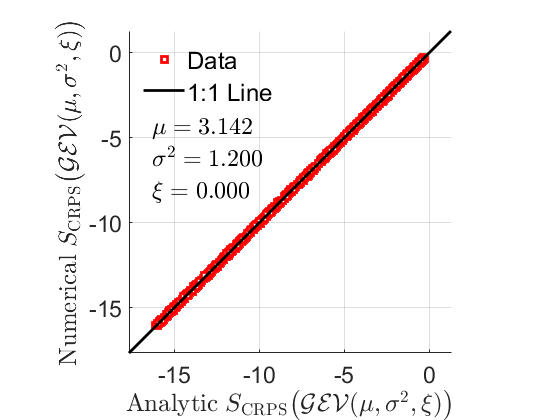

figure(1)
plot(crps_an(:,1),crps_num(:,1),'rs','markerfacecolor','w','linewidth',2);
xlabel(['${\rm Analytic}\; S_{\rm CRPS}\bigl(\mathcal{GEV}' ...
    '(\mu,\sigma^{2},\xi)\bigr)$'],'interpreter','latex','fontsize',18);
ylabel(['${\rm Numerical}\; S_{\rm CRPS}\bigl(\mathcal{GEV}' ...
    '(\mu,\sigma^{2},\xi)\bigr)$'],'interpreter','latex','fontsize',18);
axis square
r = range(crps_an(:,1));
xymin = min(crps_an(:,1)) - r/10; xymax = max(crps_an(:,1)) + r/10;
axis([xymin xymax xymin xymax]);
line([xymin xymax],[xymin xymax],'linewidth',2,'color','k');
legend('Data','1:1 Line','fontsize',18,'location','northwest'); 
legend boxoff
text(xymin + 0.07*(xymax - xymin),xymin + 0.7*(xymax-xymin), ...
    char(strcat('$\mu =',{' '},num2str(mu,'%5.3f'),'$')), ...
    'interpreter','latex','fontsize',18);
text(xymin + 0.07*(xymax - xymin),xymin + 0.6*(xymax-xymin), ...
    char(strcat('$\sigma^{2} =',{' '},num2str(s2,'%5.3f'),'$')), ...
    'interpreter','latex','fontsize',18);
text(xymin + 0.07*(xymax - xymin),xymin + 0.5*(xymax-xymin), ...
    char(strcat('$\xi =',{' '},num2str(xi,'%5.3f'),'$')), ...
    'interpreter','latex','fontsize',18);
set(gca,'fontsize',17,'box','off'); set(gcf,'color','w'); grid on

% Print some superificial errors to screen
max_err = max(abs(crps_num-crps_an(:,1)));
mean_err = mean(abs(crps_num-crps_an(:,1)));

`Plot 2: Scatter plot analytic and numerical CRPS (from integration)`

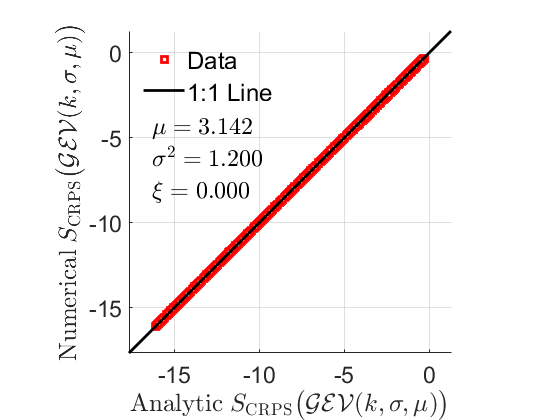

if sign(xi) == 0
    figure(2)
    plot(crps_an(:,1),crps_num(:,2),'rs', ...
        'markerfacecolor','w','linewidth',2);
    xlabel(['${\rm Analytic}\; S_{\rm CRPS}\bigl(\mathcal{GEV}' ...
        '(k,\sigma,\mu)\bigr)$'],'interpreter','latex','fontsize',18);
    ylabel(['${\rm Numerical}\; S_{\rm CRPS}\bigl(\mathcal{GEV}' ...
        '(k,\sigma,\mu)\bigr)$'],'interpreter','latex','fontsize',18);
    axis square
    r = range(crps_an(:,1));
    xymin = min(crps_an(:,1)) - r/10; xymax = max(crps_an(:,1)) + r/10;
    axis([xymin xymax xymin xymax]);
    line([xymin xymax],[xymin xymax],'linewidth',2,'color','k');
    legend('Data','1:1 Line','fontsize',18,'location','northwest'); 
    legend boxoff
    text(xymin + 0.07*(xymax - xymin),xymin + 0.7*(xymax-xymin), ...
        char(strcat('$\mu =',{' '},num2str(mu,'%5.3f'),'$')), ...
        'interpreter','latex','fontsize',18);
    text(xymin + 0.07*(xymax - xymin),xymin + 0.6*(xymax-xymin), ...
        char(strcat('$\sigma^{2} =',{' '},num2str(s2,'%5.3f'),'$')), ...
        'interpreter','latex','fontsize',18);
    text(xymin + 0.07*(xymax - xymin),xymin + 0.5*(xymax-xymin), ...
        char(strcat('$\xi =',{' '},num2str(xi,'%5.3f'),'$')), ...
        'interpreter','latex','fontsize',18);
    set(gca,'fontsize',17,'box','off'); set(gcf,'color','w'); grid on
end